# LED and Photodetectors

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIOVASCULAR AND RESPIRATORY MONITORING DEVICES

## LED


clear all
Vin(:,1)=0:0.01:10; %time;
Vin(:,2)=0:0.01/2:5;
% model_name = 'LED2';
% open_system(model_name)
% V = sdo.getParameterFromModel(model_name, 'V');
simOut = sim('LED2', 'CaptureErrors', 'on');

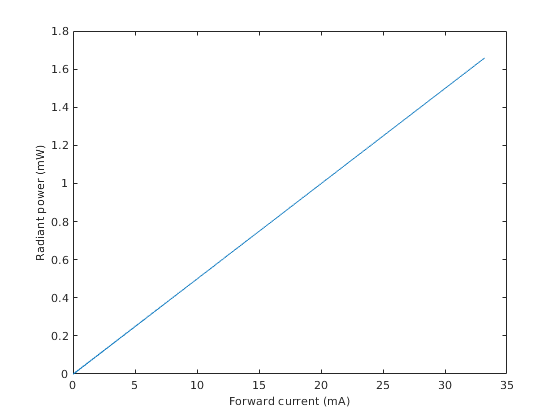

figure
plot(simOut.current_out.Data*1000,simOut.Power_out.Data*1000)
xlabel('Forward current (mA)', 'FontSize', 10)
ylabel('Radiant power (mW)', 'FontSize', 10)

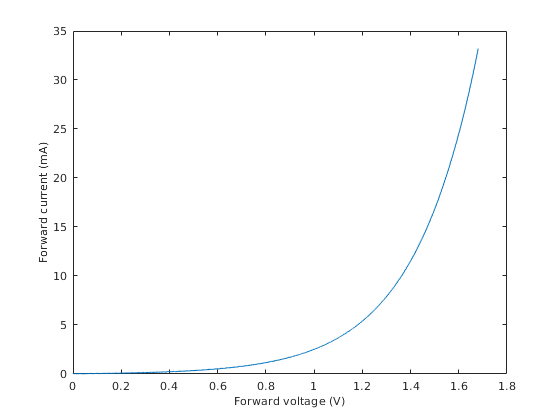

figure
plot(simOut.diode_out.Data, simOut.current_out.Data*1000)
ylabel('Forward current (mA)', 'FontSize', 10)
xlabel('Forward voltage (V)', 'FontSize', 10)

% plot(-simOut.diode_out.Data,-simOut.current_out.Data*1e6)
% xlabel(' Reverse Voltage (V)', 'FontSize', 10)
% ylabel('Reverse Light Current (µA)', 'FontSize', 10)
% 
% 
% clear all
% Irr1(:,1)=0:0.01:10; %time
% Irr1(:,2)=10; % irradiance
% Vin(:,1)=0:0.01:10; %time;
% Vin(:,2)=-5:0.01:5;
% simOut = sim('photodiode', 'CaptureErrors', 'on');
% hold on
% plot(-simOut.diode_out.Data,-simOut.current_out.Data*1e6)

## Photodetector

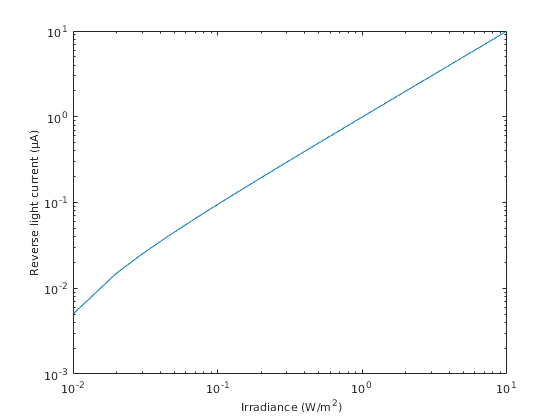

clear all

Irr1(:,1)=0:0.01:10; %time
Irr1(:,2)=0:0.01:10; % irradiance
Vin(:,1)=0:0.01:10; %time;
Vin(:,2)=5;
simOut = sim('photodiode', 'CaptureErrors', 'on');
figure
loglog(Irr1(:,2),simOut.current_out.Data(1:length(Irr1(:,2)))*1e6)
xlabel(' Irradiance (W/m^2)', 'FontSize', 10)
ylabel('Reverse light current (µA)', 'FontSize', 10)

%%
clear all
Irr1(:,1)=0:0.01:10; %time
Irr1(:,2)=0.1; % irradiance
Vin(:,1)=0:0.01:10; %time;
Vin(:,2)=-5:0.01:5;
simOut = sim('photodiode', 'CaptureErrors', 'on');
figure
a1=plot(-simOut.diode_out.Data,-simOut.current_out.Data*1e6)

a1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×9178 double]
              YData: [1×9178 double]
              ZData: [1×0 double]

  Show all properties


xlabel(' Reverse voltage (V)', 'FontSize', 10)
ylabel('Reverse light current (µA)', 'FontSize', 10)



Irr1(:,1)=0:0.01:10; %time
Irr1(:,2)=5; % irradiance
Vin(:,1)=0:0.01:10; %time;
Vin(:,2)=-5:0.01:5;
simOut = sim('photodiode', 'CaptureErrors', 'on');
hold on
a2=plot(-simOut.diode_out.Data,-simOut.current_out.Data*1e6)

a2 =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×8636 double]
              YData: [1×8636 double]
              ZData: [1×0 double]

  Show all properties


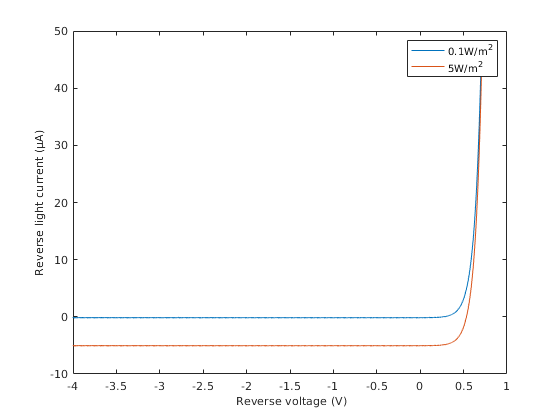

xlim([-4,1])
legend([a1,a2],["0.1W/m^2","5W/m^2"])